# readtable、writetable 详细用法案例

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

clear;clc;
% 文本内容（逗号隔开）

% 第一行内容视为列名称
T = readtable('csv_table.txt')

T = 5×6 table
      LastName      Gender    Age    Height    Weight    Smoker
    ____________    ______    ___    ______    ______    ______

    {'Smith'   }    {'M'}     38       71       176        1   
    {'Johnson' }    {'M'}     43       69       163        0   
    {'Williams'}    {'F'}     38       64       131        0   
    {'Jones'   }    {'F'}     40       67       133        0   
    {'Brown'   }    {'F'}     49       64       119        0   


% 访问其中的内容
LastName = T.LastName

LastName = 5×1 cell 数组
    {'Smith'   }
    {'Johnson' }
    {'Williams'}
    {'Jones'   }
    {'Brown'   }


% 数据部分
data_part = table2array(T(:, 3:end))

data_part =     38    71   176     1
    43    69   163     0
    38    64   131     0
    40    67   133     0
    49    64   119     0


% table 和 struct 互转
Tstruct = table2struct(T)

Tstruct = 包含以下字段的 5×1 struct 数组:
    LastName
    Gender
    Age
    Height
    Weight
    Smoker


table_struct = struct2table(Tstruct)

table_struct = 5×6 table
      LastName      Gender    Age    Height    Weight    Smoker
    ____________    ______    ___    ______    ______    ______

    {'Smith'   }    {'M'}     38       71       176        1   
    {'Johnson' }    {'M'}     43       69       163        0   
    {'Williams'}    {'F'}     38       64       131        0   
    {'Jones'   }    {'F'}     40       67       133        0   
    {'Brown'   }    {'F'}     49       64       119        0   


% table 和 cell 互转
Tcell = table2cell(T)

Tcell = 5×6 cell 数组
    {'Smith'   }    {'M'}    {[38]}    {[71]}    {[176]}    {[1]}
    {'Johnson' }    {'M'}    {[43]}    {[69]}    {[163]}    {[0]}
    {'Williams'}    {'F'}    {[38]}    {[64]}    {[131]}    {[0]}
    {'Jones'   }    {'F'}    {[40]}    {[67]}    {[133]}    {[0]}
    {'Brown'   }    {'F'}    {[49]}    {[64]}    {[119]}    {[0]}


% 需要设置列名称
cell_struct = cell2table(Tcell, 'VariableNames', T.Properties.VariableNames)

cell_struct = 5×6 table
      LastName      Gender    Age    Height    Weight    Smoker
    ____________    ______    ___    ______    ______    ______

    {'Smith'   }    {'M'}     38       71       176        1   
    {'Johnson' }    {'M'}     43       69       163        0   
    {'Williams'}    {'F'}     38       64       131        0   
    {'Jones'   }    {'F'}     40       67       133        0   
    {'Brown'   }    {'F'}     49       64       119        0   


Age = T.Age

Age =     38
    43
    38
    40
    49


cell_content = T(2, 1)

cell_content = table
     LastName  
    ___________

    {'Johnson'}


cell_content = T{2, 1}

cell_content = 1×1 cell 数组
    {'Johnson'}


% 文本内容（有缺失值）

% 如果有一个中文名，那么需要设置一下
T = readtable('csv_table_missing.txt', "VariableNamingRule", "preserve")

T = 5×6 table
      LastName        Gender      Age    Height    Weight    吸烟
    ____________    __________    ___    ______    ______    ____

    {'Smith'   }    {'M'     }     38      71       176       1  
    {'Johnson' }    {'M'     }     43      69       163       0  
    {'Williams'}    {'F'     }     38      64       131       0  
    {'Jones'   }    {'F'     }    NaN      67       133       0  
    {'Brown'   }    {0×0 char}    NaN      64       119       0  


% 访问中文标题内容
Smoker = T.("吸烟");
% 获取列明
variable_name = T.Properties.VariableNames

variable_name = 1×6 cell 数组
    {'LastName'}    {'Gender'}    {'Age'}    {'Height'}    {'Weight'}    {'吸烟'}


% 文本内容（空格隔开）

% 读取之后默认生成列名称
T = readtable('space_table.txt')

T = 3×5 table
    Var1     Var2    Var3     Var4       Var5   
    _____    ____    ____    ______    _________

    {'M'}     45      45     {'NY'}    {'true' }
    {'F'}     41      32     {'CA'}    {'false'}
    {'M'}     40      34     {'MA'}    {'false'}


% 修改第一列列名称
T.Properties.VariableNames{1} = 'Gender'

T = 3×5 table
    Gender    Var2    Var3     Var4       Var5   
    ______    ____    ____    ______    _________

    {'M'}      45      45     {'NY'}    {'true' }
    {'F'}      41      32     {'CA'}    {'false'}
    {'M'}      40      34     {'MA'}    {'false'}


% 文本内容（二进制、十六进制）

T = readtable('hex_binary.txt')

T = 3×4 table
    Var1     Var2      Var3         Var4    
    _____    ____    ________    ___________

      255    255     {'C7F9'}    {'Device1'}
      256      4     {'05BF'}    {'Device2'}
    43981    129     {'F00F'}    {'Device3'}


% 文本内容（复数）

T = readtable("complex.txt")

T = 3×2 table
    Var1    Var2
    ____    ____

     1      1+1i
     2      1+2i
     3      1+3i


complex_data = T.Var2

complex_data =    1.0000 + 1.0000i
   1.0000 + 2.0000i
   1.0000 + 3.0000i


% Excel 文件

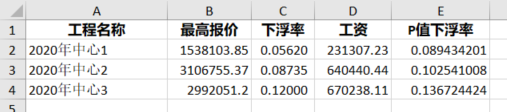

T = readtable("test.xlsx", "VariableNamingRule", "preserve")

T = 3×5 table
       工程名称         最高报价       下浮率        工资       P值下浮率
    ______________    __________    _______    __________    ________

    {'new1'      }    1.5381e+06     0.0562    2.3131e+05    0.089434
    {'2020年中心2'}    3.1068e+06    0.08735    6.4044e+05     0.10254
    {'2020年中心3'}    2.9921e+06       0.12    6.7024e+05     0.13672


% 第一个 Sheet，也可指定名称
T = readtable("test.xlsx", 'Sheet', 1, "VariableNamingRule", "preserve")

T = 3×5 table
       工程名称         最高报价       下浮率        工资       P值下浮率
    ______________    __________    _______    __________    ________

    {'new1'      }    1.5381e+06     0.0562    2.3131e+05    0.089434
    {'2020年中心2'}    3.1068e+06    0.08735    6.4044e+05     0.10254
    {'2020年中心3'}    2.9921e+06       0.12    6.7024e+05     0.13672


% 写文件
% 新建一个 table
names = T.Properties.VariableNames

names = 1×5 cell 数组
    {'工程名称'}    {'最高报价'}    {'下浮率'}    {'工资'}    {'P值下浮率'}


project_name = T.("工程名称");
bid_max = T.("最高报价");
bid_r = T.("下浮率");
salary = T.("工资");
bid_p = T.("P值下浮率");
new_table = table(project_name, bid_max, bid_r, salary, bid_p, 'VariableNames', names)

new_table = 3×5 table
       工程名称         最高报价       下浮率        工资       P值下浮率
    ______________    __________    _______    __________    ________

    {'new1'      }    1.5381e+06     0.0562    2.3131e+05    0.089434
    {'2020年中心2'}    3.1068e+06    0.08735    6.4044e+05     0.10254
    {'2020年中心3'}    2.9921e+06       0.12    6.7024e+05     0.13672


Tnew = [T; new_table]

Tnew = 6×5 table
       工程名称         最高报价       下浮率        工资       P值下浮率
    ______________    __________    _______    __________    ________

    {'new1'      }    1.5381e+06     0.0562    2.3131e+05    0.089434
    {'2020年中心2'}    3.1068e+06    0.08735    6.4044e+05     0.10254
    {'2020年中心3'}    2.9921e+06       0.12    6.7024e+05     0.13672
    {'new1'      }    1.5381e+06     0.0562    2.3131e+05    0.089434
    {'2020年中心2'}    3.1068e+06    0.08735    6.4044e+05     0.10254
    {'2020年中心3'}    2.9921e+06       0.12    6.7024e+05     0.13672


% 保存
writetable(Tnew, 'Tnew.xlsx');

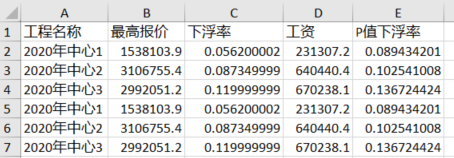

writetable(Tnew, 'Tnew.txt');

% 空格隔开
writetable(Tnew, 'Tnew_space.txt', "Delimiter", ' ');

% 修改带有格式的 Excel 文件

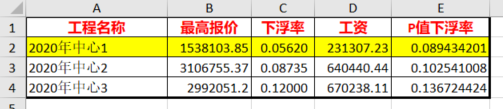

T = readtable("test_format.xlsx", "VariableNamingRule", "preserve")

T = 3×5 table
       工程名称         最高报价       下浮率        工资       P值下浮率
    ______________    __________    _______    __________    ________

    {'new1'      }    1.5381e+06     0.0562    2.3131e+05    0.089434
    {'2020年中心2'}    3.1068e+06    0.08735    6.4044e+05     0.10254
    {'2020年中心3'}    2.9921e+06       0.12    6.7024e+05     0.13672


% 修改内容
T.("工程名称"){1} = 'new1'

T = 3×5 table
       工程名称         最高报价       下浮率        工资       P值下浮率
    ______________    __________    _______    __________    ________

    {'new1'      }    1.5381e+06     0.0562    2.3131e+05    0.089434
    {'2020年中心2'}    3.1068e+06    0.08735    6.4044e+05     0.10254
    {'2020年中心3'}    2.9921e+06       0.12    6.7024e+05     0.13672


% 覆盖源文件
writetable(T, 'test_format.xlsx', "PreserveFormat", true);